# Time-frequency plot on all electrodes 

This example demonstrates some of the power of low-level scripting that  goes beyond the scope of functions currently available through the EEGLAB  graphical interface. 

Below we run this script on the tutorial epoched  dataset. The [tftopo.m](http://sccn.ucsd.edu/eeglab/locatefile.php?file=tftopo.m) function is a powerful function that allows plotting time-frequency decompositions across all channels.

#### Loading data

eeglab; close; % add path

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is ~/eeg_options.m


Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "Fieldtrip-lite" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "Fileio" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v1.2.6 (see >> help eegplugin_iclabel) - new version 1.3 available
EEGLAB: adding "MFFMatlabIO" v3.5 (see >> help eegplugin_mffmatlabio)
EEGLAB: adding "bva-io" v1.6 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.2 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v3.0 (see >> help eegplugin_dipfit) - new version 3.4 available
EEGLAB: adding "firfilt" v2.1 (see >> help eegplugin_firfilt) - new version 2.4 available
EEGLAB: adding "musemonitor" v3.1 (see >> help eegplugin_musemonitor) - new version 3.2 available
You are using the latest version of EEGLAB.


eeglabp = fileparts(which('eeglab.m'));
EEG = pop_loadset(fullfile(eeglabp, 'sample_data', 'eeglab_data_epochs_ica.set'));

pop_loadset(): loading file /home/claire/Applications/eeglab/sample_data/eeglab_data_epochs_ica.set ...
Reading float file '/home/claire/Applications/eeglab/sample_data/eeglab_data_epochs_ica.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


#### Computing measures on each electrode

for elec = 1:EEG.nbchan
    [ersp,itc,powbase,times,freqs,erspboot,itcboot] = pop_newtimef(EEG,...
    1, elec, [EEG.xmin EEG.xmax]*1000, [3 0.5], 'maxfreq', 50, 'padratio', 16, ...
    'plotphase', 'off', 'timesout', 60, 'alpha', .05, 'plotersp','off', 'plotitc','off');
    if elec == 1  % create empty arrays if first electrode
        allersp = zeros([ size(ersp) EEG.nbchan]);
        allitc = zeros([ size(itc) EEG.nbchan]);
        allpowbase = zeros([ size(powbase) EEG.nbchan]);
        alltimes = zeros([ size(times) EEG.nbchan]);
        allfreqs = zeros([ size(freqs) EEG.nbchan]);
        allerspboot = zeros([ size(erspboot) EEG.nbchan]);
        allitcboot = zeros([ size(itcboot) EEG.nbchan]);
    end
    allersp (:,:,elec) = ersp;
    allitc (:,:,elec) = itc;
    allpowbase (:,:,elec) = powbase;
    alltimes (:,:,elec) = times;
    allfreqs (:,:,elec) = freqs;
    allerspboot (:,:,elec) = erspboot;
    allitcboot (:,:,elec) = itcboot;
end

Permutation analysis will use data in (pre-0) baseline subwindows only.
Computing Event-Related Spectral Perturbation (ERSP) and
  Inter-Trial Phase Coherence (ITC) images based on 80 trials
  of 384 frames sampled at 128 Hz.
Each trial contains samples from -1000 ms before to
  1992 ms after the timelocking event.
Only significant values (permutation statistics p<0.05) will be colored;
  non-significant values will be plotted in green
  Image frequency direction: normal
Using 3 cycles at lowest frequency to 12.5 at highest.
Generating 60 time points (-722.7 to 1714.8 ms)
Finding closest points for time variable
Time values for time/freq decomposition is not perfectly uniformly distributed
The window size used is 71 samples (554.688 ms) wide.
Estimating 353 linear-spaced frequencies from 6.0 Hz to 50.0 Hz.
Processing time point (of 60): 10 20 30 40 50 60
Computing the mean baseline spectrum
   18 permutation statistics windows in baseline (times<1).

Permutation statistics baseline len

#### Plot

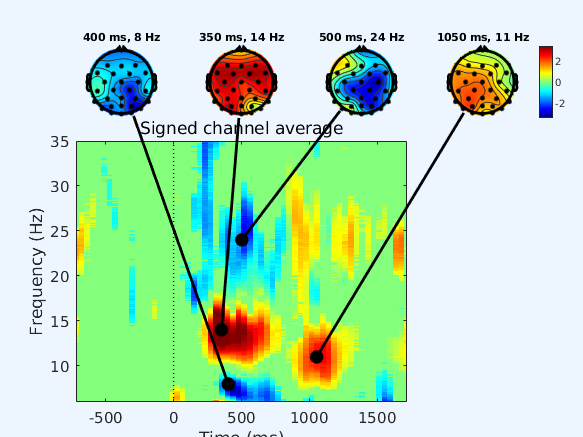

tftopo(): error in 'signifs' array size not compatible with data size, trying to transpose.
Applying 'signifs' mask by zeroing non-significant values


Computing average across channels (mask for at least 6 non-zeros values at each time/freq)


figure;
tftopo(allersp,alltimes(:,:,1),allfreqs(:,:,1),'mode','ave','limits',...
[nan nan nan 35 -1.5 1.5],'signifs', allerspboot, 'sigthresh', [6], 'timefreqs', ...
[400 8; 350 14; 500 24; 1050 11], 'chanlocs', EEG.chanlocs);